**Question 1: Extract the profile data from 5904859QC.TXT into Matlab in a user friendly format.**

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 40);

% Specify range and delimiter
opts.DataLines = [76, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Cruise", "Station", "Type", "mondayyr", "hhmm", "LonE", "LatN", "QF", "Pressuredbar", "QF1", "TemperatureC", "QF2", "Salinitypss", "QF3", "Sigma_thetakgm3", "QF4", "Depthm", "QF5", "Oxygenmolkg", "QF6", "OxygenSat", "QF7", "Nitratemolkg", "QF8", "Chl_amgm3", "QF9", "b_bp7001m", "QF10", "POCmmolm3", "QF11", "pHinsituTotal", "QF12", "pH25CTotal", "QF13", "TALK_LIARmolkg", "QF14", "DIC_LIARmolkg", "QF15", "pCO2_LIARatm", "QF16"];
opts.VariableTypes = ["double", "double", "categorical", "datetime", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Type", "hhmm"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "mondayyr", "InputFormat", "MM/dd/yyyy");
opts = setvaropts(opts, ["Cruise", "Station", "LonE", "LatN", "QF", "Pressuredbar", "QF1", "TemperatureC", "QF2", "Salinitypss", "QF3", "Sigma_thetakgm3", "QF4", "Depthm", "QF5", "Oxygenmolkg", "QF6", "OxygenSat", "QF7", "Nitratemolkg", "QF8", "Chl_amgm3", "QF9", "b_bp7001m", "QF10", "POCmmolm3", "QF11", "pHinsituTotal", "QF12", "pH25CTotal", "QF13", "TALK_LIARmolkg", "QF14", "DIC_LIARmolkg", "QF15", "pCO2_LIARatm", "QF16"], "ThousandsSeparator", ",");
Data = readtable("5904859QC.TXT",opts)

Data = 10522×40 table
      Cruise      Station    Type     mondayyr      hhmm      LonE      LatN      QF    Pressuredbar    QF1    TemperatureC    QF2    Salinitypss    QF3    Sigma_thetakgm3    QF4    Depthm    QF5    Oxygenmolkg    QF6    OxygenSat    QF7    Nitratemolkg    QF8    Chl_amgm3    QF9    b_bp7001m    QF10    POCmmolm3    QF11    pHinsituTotal    QF12    pH25CTotal    QF13    TALK_LIARmolkg


clear opts

**Question 2: Make a 2-panel plot. In the first panel, plot all nitrate data vs depth, and in the second panel do the same but for good quality nitrate data only. **

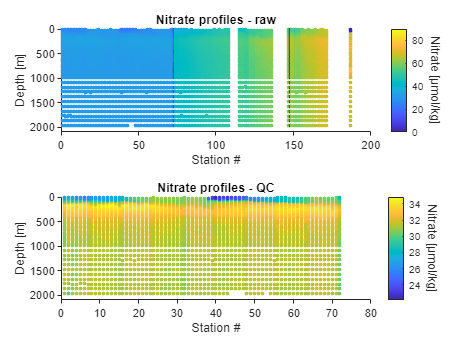

% Load in the raw data from the table
Depth = Data.Depthm;
Stn = Data.Station;
Nitrate = Data.Nitratemolkg;

% Filter the data based on the Nitrate QF8
Depth_filt=Depth(Data.QF8==0);
Stn_filt=Stn(Data.QF8==0);
Nitrate_filt=Nitrate(Data.QF8==0);

figure;

% Plot the two scatter plots
tiledlayout(2,1)

% Raw Nitrate plot
ax1 = nexttile;
scatter(ax1,Stn,Depth,8,Nitrate,'filled')
set(gca, 'YDir','reverse');
set(gca,'clim',[0 max(Nitrate)]);
set(gca,'ylim',[0 2100])
set(gca,'TickDir','out');
title("Nitrate profiles - raw");
ylabel("Depth [m]");
xlabel("Station #");
cbar1 = colorbar;
cbar1.Label.String = "Nitrate [µmol/kg]";
cbar1.Label.FontSize = 9;
cbar1.Label.Rotation=-90;

% QC Nitrate plot
ax2 = nexttile;
scatter(ax2,Stn_filt,Depth_filt,8,Nitrate_filt,'filled')
set(gca, 'YDir','reverse');
set(gca,'clim',[min(Nitrate_filt) max(Nitrate_filt)]);
set(gca,'ylim',[0 2100]);
set(gca,'TickDir','out');
title("Nitrate profiles - QC");
ylabel("Depth [m]");
xlabel("Station #");
cbar2 = colorbar;
cbar2.Label.String = "Nitrate [µmol/kg]";
cbar2.Label.FontSize = 9;
cbar2.Label.Rotation=-90;

**Question 3: Make an average depth profile to 1000 m of temperature, with ± 1 standard deviation as shaded areas. Data should be binned to 5 m bins, and only use QF of 0 (good data)**

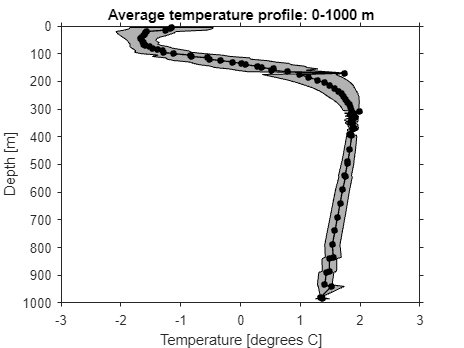

% Sort the data into descending order based on Pressure
Data_sorted = sortrows(Data, "Depthm");

% Filter pressure and temperature by the temperature QF2
Depth_sorted_filt = Data_sorted.Depthm(Data_sorted.QF2==0 & Data_sorted.Depthm<=1000 & Data_sorted.QF5==0);
Temp_sorted_filt = Data_sorted.TemperatureC(Data_sorted.QF2==0 & Data_sorted.Depthm<=1000 & Data_sorted.QF5==0);

% Create evenly spaced depth bins from 0 to 1000 with 5 m spacing
dBins = 0:5:1000;

% Initialize variables to store mean temperatures for each depth bin
Temp_mean = zeros(1, numel(dBins)-1);
Temp_std = zeros(1, numel(dBins)-1);

% Calculate mean temperature for each depth bin
for i = 1:numel(dBins)-1
    % Find indices of depths falling within the current depth bin
    indices = find(Depth_sorted_filt >= dBins(i) & Depth_sorted_filt < dBins(i+1));
    
    % Calculate mean and std of temperature for the current depth bin
    Temp_mean(i) = mean(Temp_sorted_filt(indices));
    Temp_std(i) = std(Temp_sorted_filt(indices));
end

% Remove NaNs from vectors to get rid of gaps
dBins = dBins(~isnan(Temp_mean));
Temp_mean = rmmissing(Temp_mean);
Temp_std = rmmissing(Temp_std);

% Plot average temperature profile
figure;

plot(Temp_mean,dBins,"k.-",...
    'LineWidth',1,...
    'MarkerSize',15)
hold on

% Plot the shaded region between +-1 std
stdLower = Temp_mean-Temp_std;
stdUpper = Temp_mean+Temp_std;

yFill = [dBins, fliplr(dBins)];
xFill = [stdLower, fliplr(stdUpper)];
fill(xFill, yFill, 'k','FaceAlpha',0.3)

set(gca, 'YDir','reverse');
set(gca, 'xlim',[-3 3]);
set(gca,'TickDir','out');
title("Average temperature profile: 0-1000 m");
ylabel("Depth [m]");
xlabel("Temperature [degrees C]");

**Question 4: Make a contour plot of the upper 300 m of Oxygen, only using good data. **

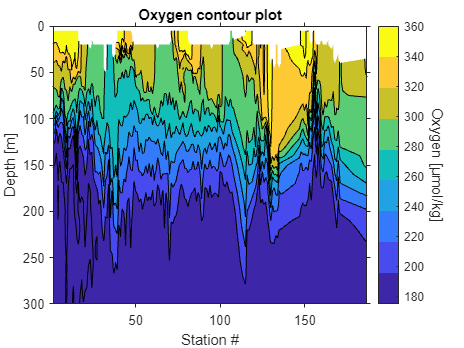

% Sort the data into descending order based on depth
Data_sorted = sortrows(Data, "Depthm");

% Filter data based on the Oxygen QF6 and 300 m depth limit, as well as
% good quality depth estimates
Depth_sorted_filt = Data_sorted.Depthm(Data_sorted.QF6==0 & Data_sorted.Depthm<=300 & Data_sorted.QF5==0);
Stn_sorted_filt = Data_sorted.Station(Data_sorted.QF6==0 & Data_sorted.Depthm<=300 & Data_sorted.QF5==0);
Oxy_sorted_filt = Data_sorted.Oxygenmolkg(Data_sorted.QF6==0 & Data_sorted.Depthm<=300 & Data_sorted.QF5==0);

% Since data contains non-uniform depths per station, a standardized 2D array must be created
% to make a contour plot, which relies on uniform dimensions
unique_stns = unique(Stn_sorted_filt);
depth = [5:5:100 110:10:300];

% Create an empty array with depth as rows and stations as columns
new_oxy = NaN(length(depth), length(unique_stns));

% Run a for loop to populate new_oxy array with oxygen data for each station
for i = 1:length(unique_stns)
    % Call oxygen data from the specific station
    dat = Oxy_sorted_filt(Stn_sorted_filt==unique_stns(i));
    % Populate the array
    new_oxy(length(depth)-length(dat)+1:end,i) = dat;
end

% Make the contour plot
figure;

contourf(unique_stns,depth,new_oxy)
set(gca, 'YDir','reverse');
set(gca,'ylim',[0 300]);
set(gca,'TickDir','out');
title("Oxygen contour plot");
ylabel("Depth [m]");
xlabel("Station #");
cmap = parula(9);
colormap(cmap);
cbar = contourcbar;
cbar.Label.String = "Oxygen [µmol/kg]";
cbar.Label.FontSize = 11;
cbar.Label.Rotation=-90;